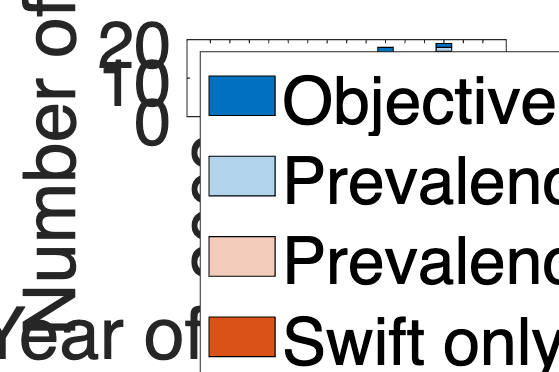

fig = figure;

fig.Position = [100, 100, 1200, 800]; % Width: 1200, Height: 600

% Create the bar chart
b = bar([2008:2022], beginning, 'stacked');
b(1).FaceColor = "#D95319";
b(2).FaceColor = "#F3CBBA";
b(3).FaceColor = "#B2D4EB";
b(4).FaceColor = "#0072BD";

% Set the font size for the legend, axes labels and ticks
lgd = legend("Swift only", "Prevalence of Swift", "Prevalence of Objective-C", "Objective-C only", 'Location', 'northwest');
set(lgd, 'FontSize', 30);
xlabel("Year of the first commit", 'FontSize', 30);
ylabel("Number of apps", 'FontSize', 30);
set(gca, 'FontSize', 30);

% Adjust figure's paper size and position to match its content
set(gcf, 'PaperPositionMode', 'auto');
set(gcf, 'PaperUnits', 'points');
set(gcf, 'PaperSize', [1200 800]);
set(gcf, 'PaperPosition', [0 0 1200 800]);

% Save the figure as a cropped PDF
print(gcf, 'lang-first-commit', '-dpdf', '-r0');